clc
clear all;

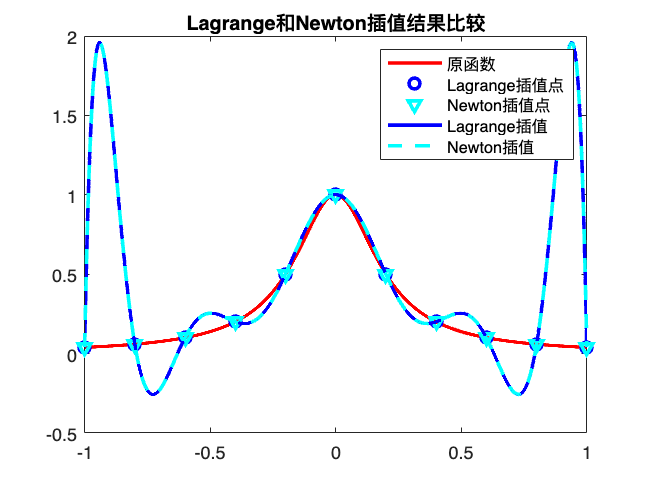

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The comparison between Lagrange interpolation 
% and Newton interpolation
% There should be no difference.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
y=@(x)1./(1+25.*x.^2);             % Function to be interpolated

bound=1;                           % Boundary
n=11;                              % Number of interpolation points
x0=linspace(-bound,bound,n);       % Interpolation points (x)
y0=y(x0);                          % Interpolation points (y)
                                   
x_base=-bound:2*bound/(1000*n):bound;
y_base=y(x_base);

% Lagrange interpolation
y_lagrange=lagrange_interp(x_base,x0,y0);

% Newton interpolation
y_newton=newton_interp(x_base,x0,y0);

% Plot the real curve
plot(x_base,y_base,"-",'LineWidth',2,'Color','r');hold on;

% Plot the interpolated points
plot(x0,y0,"o",'LineWidth',2,'Color','b');hold on;
plot(x0,y0,"v",'LineWidth',2,'Color','c');hold on;

% Plot the interpolated curve
plot(x_base,y_lagrange,"-",'LineWidth',2,'Color','b');hold on;
plot(x_base,y_newton,"--",'LineWidth',2,'Color','c');hold off;

legend('原函数','Lagrange插值点','Newton插值点','Lagrange插值','Newton插值');
title("Lagrange和Newton插值结果比较");

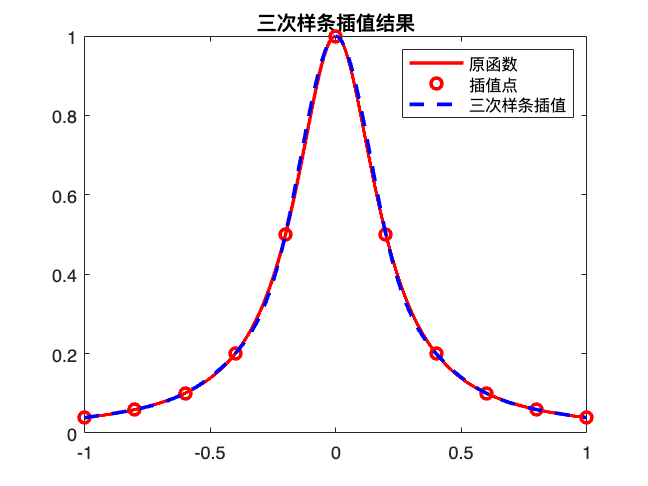

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cubic spline interpolation
% Compare the result of the interpolation 
% methods with polynominal interpolation.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Spline interpolation
y_spline=y_base;
for i=1:length(y_spline)
    y_spline(i)=spline_interp(x_base(i),x0,y0);
end

% Plot the real curve
plot(x_base,y_base,"-",'LineWidth',2,'Color','r');hold on;

% Plot the interpolated points
plot(x0,y0,"o",'LineWidth',2,'Color','r');hold on;


% Plot the interpolated curve
plot(x_base,y_spline,"--",'LineWidth',2,'Color','b');hold off;

legend('原函数','插值点','三次样条插值');
title("三次样条插值结果");

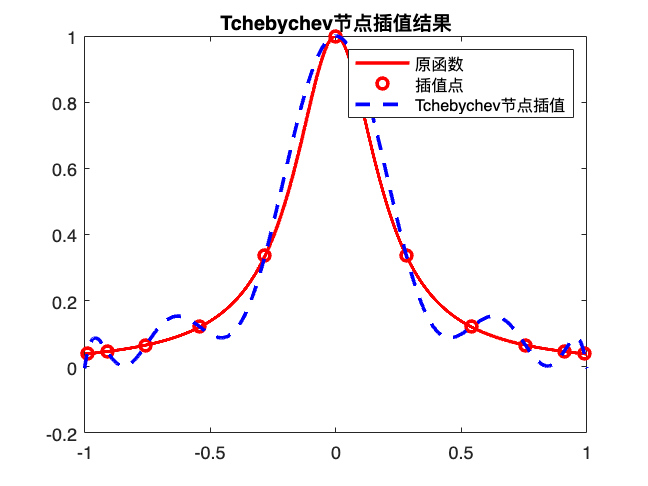

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Comparison between different node sequences 
% of polynominal interpolation.
% Tchebychev nodes and equidistant nodes, 
% pay attention to Runge phenomenon.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Tchebychev nodes
x_tche=zeros([n,1]);
for i=1:length(x_tche)
    x_tche(i)=cos((2*i-1)*pi/(2*(n)));
end

% Lagrange interpolation
y_tche=zeros(size(x_tche));
for i=1:length(x_tche)
    y_tche(i)=y(x_tche(i));
end
y_tche_interp=lagrange_interp(x_base,x_tche,y_tche);

% Plot the real curve
plot(x_base,y_base,"-",'LineWidth',2,'Color','r');hold on;

% Plot the interpolated points
plot(x_tche,y_tche,"o",'LineWidth',2,'Color','r');hold on;


% Plot the interpolated curve
plot(x_base,y_tche_interp,"--",'LineWidth',2,'Color','b');hold off;

legend('原函数','插值点','Tchebychev节点插值');
title("Tchebychev节点插值结果");

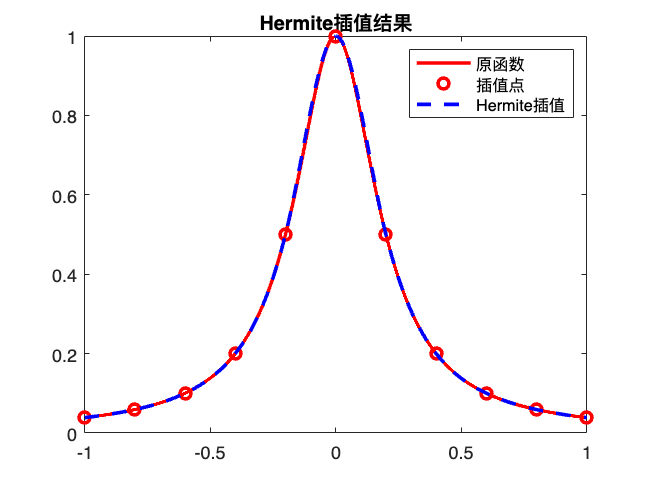

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Hermite spline interpolation
% Compare the result of the interpolation 
% methods with polynominal interpolation.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
syms x;
y=y(x);
dy=diff(y);
dy0=zeros(size(x0));
for i=1:length(x0)
    dy0(i)=subs(dy,x,x0(i));
end
y_hermite=hermite_interp(x0,y0,dy0,x_base);

% Plot the real curve
plot(x_base,y_base,"-",'LineWidth',2,'Color','r');hold on;

% Plot the interpolated points
plot(x0,y0,"o",'LineWidth',2,'Color','r');hold on;

% Plot the interpolated curve
plot(x_base,y_hermite,"--",'LineWidth',2,'Color','b');hold off;

legend('原函数','插值点','Hermite插值');
title("Hermite插值结果");